%% AE 6355 - Individual Project - Monte Carlo Landing Ellipse
% Minor Upgrade #4: disperses atmospheric density, entry flight path
% angle, entry velocity, and initial latitude/longitude to produce a
% landing footprint (ellipse) for the Stardust-conditions case, using
% the same EquiFlow-based aerodynamics and non-planar EOM as the main
% validation run. See report Sec. 2.8, 3.8.
%
% Dispersions (1-sigma, Gaussian, truncated at +/-3 sigma):
%   Atmospheric density bias : 10%   (single multiplicative bias per
%                                      trial, held constant along the
%                                      trajectory)
%   Entry flight path angle  : 0.2 deg
%   Entry velocity           : 10 m/s
%   Initial latitude         : 0.05 deg
%   Initial longitude        : 0.05 deg

clear; clc; close all;
rng(1);   % fixed seed for reproducibility

%% -----------------------------------------------------------------
%% NOMINAL CASE (matches EDL_BaseProject.m Stardust configuration)
%% -----------------------------------------------------------------
g0 = 9.81;
Re = 6378150;
omega_earth = 7.292115147e-5;   % rad/s
gamma_cutoff = deg2rad(85);     % avoids EOM_6DOF's 1/cos(gamma) singularity; see report Sec. 2.2

V0_nom     = 12799;
gamma0_nom = deg2rad(8.21);
h0         = 6503.14e3 - Re;
psi0_nom   = deg2rad(102.9);
phi0_nom   = 0;
theta0_nom = 0;

m_veh   = 46;
d_veh   = 0.8128;
rn      = 0.2202;
rb      = d_veh/2;
delta_c = 60*pi/180;
A_ref   = pi*rb^2;

gamma_air           = 1.4;
R_air               = 287;
T2_react_threshold  = 800;
M_transonic_cutoff  = 1.2;

skip_altitude = h0 + 100;

V_grid = linspace(0, 14000, 20);
h_grid = linspace(0, 130000, 20);
assert(skip_altitude <= max(h_grid), 'skip_altitude must lie inside the aerodynamic-table altitude range.');

cpmax_formula_version = 3;
species_model = 'earth10';
CD_table_cache_file = 'stardust_CD_table_cache.mat';

cache_valid = false;
if isfile(CD_table_cache_file)
    try
        loaded = load(CD_table_cache_file, 'CD_interp', 'V_grid', 'h_grid', 'rn', 'rb', 'delta_c', ...
            'gamma_air', 'R_air', 'T2_react_threshold', 'M_transonic_cutoff', ...
            'cpmax_formula_version', 'species_model');
        cache_valid = isequal(loaded.V_grid, V_grid) && isequal(loaded.h_grid, h_grid) ...
            && loaded.rn==rn && loaded.rb==rb && loaded.delta_c==delta_c ...
            && loaded.gamma_air==gamma_air && loaded.R_air==R_air ...
            && loaded.T2_react_threshold==T2_react_threshold ...
            && loaded.M_transonic_cutoff==M_transonic_cutoff ...
            && loaded.cpmax_formula_version==cpmax_formula_version ...
            && strcmp(loaded.species_model, species_model);
    catch
        cache_valid = false;
    end
end
if cache_valid
    CD_interp = loaded.CD_interp;
    fprintf('Loaded cached CD(V,h) table from %s.\n', CD_table_cache_file);
else
    fprintf('Building CD(V,h) table...\n');
    CD_interp = build_stardust_CD_table(V_grid, h_grid, rn, rb, delta_c, species_model, ...
        gamma_air, R_air, T2_react_threshold, M_transonic_cutoff, d_veh);
    save(CD_table_cache_file, 'CD_interp', 'V_grid', 'h_grid', 'rn', 'rb', 'delta_c', ...
        'gamma_air', 'R_air', 'T2_react_threshold', 'M_transonic_cutoff', ...
        'cpmax_formula_version', 'species_model', 'd_veh');
end

Loaded cached CD(V,h) table from stardust_CD_table_cache.mat.



rho0 = 1.225;
H    = 7200;

%% -----------------------------------------------------------------
%% DISPERSIONS (1-sigma)
%% -----------------------------------------------------------------
n_trials = 2000;

sigma_rho_frac = 0.10;         % fractional density bias
sigma_gamma    = deg2rad(0.2); % rad
sigma_V        = 10;           % m/s
sigma_phi      = deg2rad(0.05);% rad
sigma_theta    = deg2rad(0.05);% rad

randn_clipped = @(sigma) max(min(sigma*randn(), 3*sigma), -3*sigma);

%% -----------------------------------------------------------------
%% MONTE CARLO LOOP
%% -----------------------------------------------------------------
ode_settings = {'RelTol',1e-8, 'AbsTol',[1e-3 1e-10 1e-3 1e-10 1e-10 1e-10], 'MaxStep',0.5};
tspan = [0 2000];

phi_land   = nan(n_trials,1);
theta_land = nan(n_trials,1);
outcome_list = cell(n_trials,1);

fprintf('Running %d Monte Carlo trials...\n', n_trials);

Running 2000 Monte Carlo trials...


mc_tic = tic;
for i = 1:n_trials
    delta_rho = randn_clipped(sigma_rho_frac);
    gamma0_i  = gamma0_nom + randn_clipped(sigma_gamma);
    V0_i      = V0_nom + randn_clipped(sigma_V);
    phi0_i    = phi0_nom + randn_clipped(sigma_phi);
    theta0_i  = theta0_nom + randn_clipped(sigma_theta);

    params.Re = Re;
    params.beta = @(V,h) m_veh./(lookup_CD_checked(CD_interp, V_grid, h_grid, V, h).*A_ref);
    params.LD   = @(V,h) 0;
    params.sigma = @(t) 0;
    params.g_fun = @(h) g0*(Re/(Re+max(h,0)))^2;
    params.rho_fun = @(h) rho0*(1+delta_rho)*exp(-max(h,0)/H);
    params.gravity_model = 'inverse_square';
    params.omega = omega_earth;

    x0_i = [V0_i; gamma0_i; h0; psi0_nom; phi0_i; theta0_i];

    [outcome, phi_f, theta_f] = run_dispersed_trajectory(x0_i, params, tspan, ode_settings, ...
        skip_altitude, gamma_air, R_air, M_transonic_cutoff, CD_interp, V_grid, h_grid, m_veh, A_ref, gamma_cutoff);

    outcome_list{i} = outcome;
    if strcmp(outcome, 'ground impact')
        phi_land(i) = phi_f;
        theta_land(i) = theta_f;
    end

    if mod(i,50)==0
        fprintf('  %d/%d trials complete (%.1f s elapsed)\n', i, n_trials, toc(mc_tic));
    end
end

  50/2000 trials complete (0.6 s elapsed)
  100/2000 trials complete (1.1 s elapsed)
  150/2000 trials complete (1.6 s elapsed)
  200/2000 trials complete (2.1 s elapsed)
  250/2000 trials complete (2.6 s elapsed)
  300/2000 trials complete (3.1 s elapsed)
  350/2000 trials complete (3.6 s elapsed)
  400/2000 trials complete (4.1 s elapsed)
  450/2000 trials complete (4.6 s elapsed)
  500/2000 trials complete (5.1 s elapsed)
  550/2000 trials complete (5.6 s elapsed)
  600/2000 trials complete (6.1 s elapsed)
  650/2000 trials complete (6.6 s elapsed)
  700/2000 trials complete (7.1 s elapsed)
  750/2000 trials complete (7.6 s elapsed)
  800/2000 trials complete (8.1 s elapsed)
  850/2000 trials complete (8.6 s elapsed)
  900/2000 trials complete (9.1 s elapsed)
  950/2000 trials complete (9.6 s elapsed)
  1000/2000 trials complete (10.1 s elapsed)
  1050/2000 trials complete (10.6 s elapsed)
  1100/2000 trials complete (11.1 s elapsed)
  1150/2000 trials complete (11.6 s elapsed)
  12

fprintf('Monte Carlo complete in %.1f min.\n', toc(mc_tic)/60);

Monte Carlo complete in 0.3 min.



n_impact = nnz(~isnan(phi_land));
n_skip   = nnz(strcmp(outcome_list, 'atmospheric skip-out'));
n_other  = n_trials - n_impact - n_skip;
fprintf('Outcomes: %d ground impact, %d atmospheric skip-out, %d other\n', n_impact, n_skip, n_other);

Outcomes: 2000 ground impact, 0 atmospheric skip-out, 0 other



%% -----------------------------------------------------------------
%% LANDING ELLIPSE (downrange/crossrange, local flat-Earth approx)
%% -----------------------------------------------------------------
valid = ~isnan(phi_land);
downrange_km  = Re*(theta_land(valid)-theta0_nom)/1000;
crossrange_km = Re*(phi_land(valid)-phi0_nom)/1000;

mean_dr = mean(downrange_km);
mean_cr = mean(crossrange_km);
cov_mat = cov([downrange_km, crossrange_km]);

fprintf('\n--- LANDING ELLIPSE SUMMARY (%d successful trials) ---\n', n_impact);


--- LANDING ELLIPSE SUMMARY (2000 successful trials) ---


fprintf('Mean landing point: downrange=%.2f km, crossrange=%.2f km\n', mean_dr, mean_cr);

Mean landing point: downrange=-171.30 km, crossrange=747.17 km


fprintf('Std dev: downrange=%.2f km, crossrange=%.2f km\n', std(downrange_km), std(crossrange_km));

Std dev: downrange=8.78 km, crossrange=29.02 km



[eigvec, eigval] = eig(cov_mat);
[eigval_sorted, idx] = sort(diag(eigval), 'descend');
eigvec_sorted = eigvec(:, idx);
semi_major_1sigma = sqrt(eigval_sorted(1));
semi_minor_1sigma = sqrt(eigval_sorted(2));
ellipse_angle = atan2(eigvec_sorted(2,1), eigvec_sorted(1,1));

fprintf('1-sigma ellipse: semi-major=%.2f km, semi-minor=%.2f km, orientation=%.1f deg from downrange axis\n', ...
    semi_major_1sigma, semi_minor_1sigma, rad2deg(ellipse_angle));

1-sigma ellipse: semi-major=29.80 km, semi-minor=5.59 km, orientation=103.4 deg from downrange axis


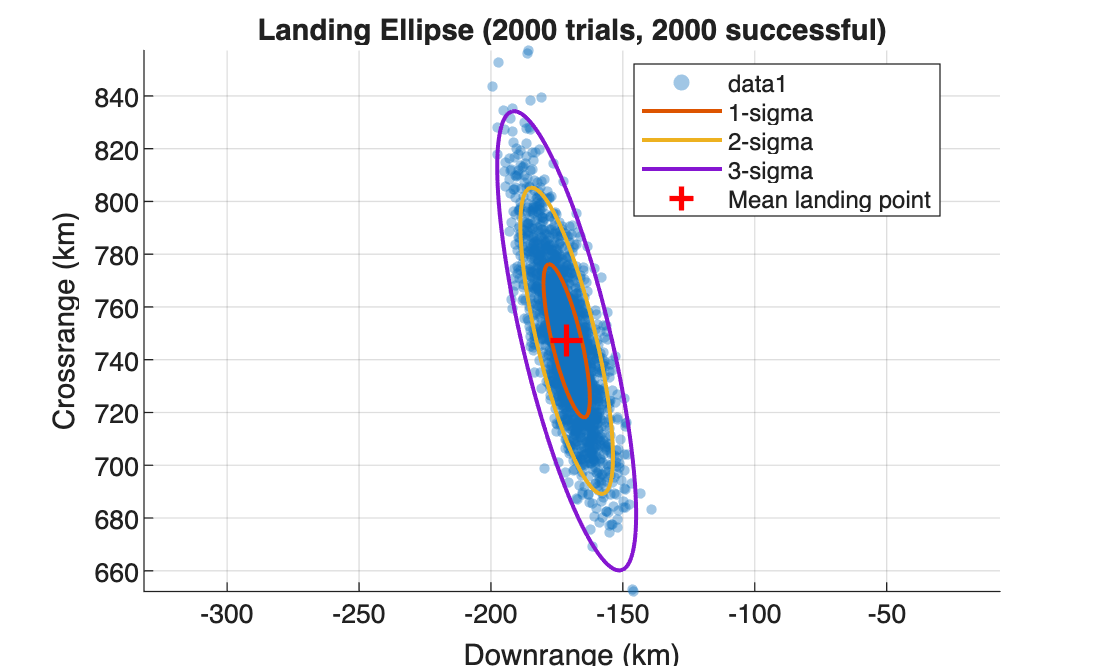


% Scatter data: all successful trial landing points
T_mc_scatter = table(downrange_km, crossrange_km, ...
    'VariableNames', {'downrange_km','crossrange_km'});
writetable(T_mc_scatter, 'stardust_mc_scatter.csv');

% Ellipse boundary curves (1, 2, 3-sigma), as x,y point sets for plotting
theta_circ = linspace(0, 2*pi, 100)';
R_rot = [cos(ellipse_angle) -sin(ellipse_angle); sin(ellipse_angle) cos(ellipse_angle)];

ellipse_1s = R_rot * [semi_major_1sigma*1*cos(theta_circ)'; semi_minor_1sigma*1*sin(theta_circ)'];
ellipse_2s = R_rot * [semi_major_1sigma*2*cos(theta_circ)'; semi_minor_1sigma*2*sin(theta_circ)'];
ellipse_3s = R_rot * [semi_major_1sigma*3*cos(theta_circ)'; semi_minor_1sigma*3*sin(theta_circ)'];

T_mc_ellipses = table( ...
    mean_dr+ellipse_1s(1,:)', mean_cr+ellipse_1s(2,:)', ...
    mean_dr+ellipse_2s(1,:)', mean_cr+ellipse_2s(2,:)', ...
    mean_dr+ellipse_3s(1,:)', mean_cr+ellipse_3s(2,:)', ...
    'VariableNames', {'x_1sigma','y_1sigma','x_2sigma','y_2sigma','x_3sigma','y_3sigma'});
writetable(T_mc_ellipses, 'stardust_mc_ellipses.csv');

% Summary statistics (one row)
T_mc_summary = table(mean_dr, mean_cr, std(downrange_km), std(crossrange_km), ...
    semi_major_1sigma, semi_minor_1sigma, rad2deg(ellipse_angle), n_impact, n_trials, ...
    'VariableNames', {'mean_downrange_km','mean_crossrange_km','std_downrange_km', ...
    'std_crossrange_km','semi_major_km','semi_minor_km','orientation_deg','n_impact','n_trials'});
writetable(T_mc_summary, 'stardust_mc_summary.csv');

figure;
scatter(downrange_km, crossrange_km, 15, 'filled', 'MarkerFaceAlpha', 0.4); hold on;
theta_circ = linspace(0, 2*pi, 100);
for n_sigma = 1:3
    ellipse_pts = [semi_major_1sigma*n_sigma*cos(theta_circ); semi_minor_1sigma*n_sigma*sin(theta_circ)];
    R_rot = [cos(ellipse_angle) -sin(ellipse_angle); sin(ellipse_angle) cos(ellipse_angle)];
    ellipse_rot = R_rot*ellipse_pts;
    plot(mean_dr+ellipse_rot(1,:), mean_cr+ellipse_rot(2,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('%d-sigma', n_sigma));
end
plot(mean_dr, mean_cr, 'r+', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Mean landing point');
xlabel('Downrange (km)'); ylabel('Crossrange (km)');
title(sprintf('Landing Ellipse (%d trials, %d successful)', n_trials, n_impact));
legend('Location','best'); axis equal; grid on;



%% ===================================================================
%% LOCAL FUNCTIONS
%% ===================================================================

function [outcome, phi_f, theta_f] = run_dispersed_trajectory(x0, params, tspan, ode_settings, ...
    skip_altitude, gamma_air, R_air, M_transonic_cutoff, CD_interp, V_grid, h_grid, m_veh, A_ref, gamma_cutoff)
% Runs one two-segment (Mach-freeze) non-planar trajectory to impact,
% skip-out, or gamma cutoff, mirroring EDL_BaseProject.m's integration
% logic. Returns only the outcome and final latitude/longitude.
% gamma_cutoff is treated as a landing outcome, not a separate case,
% since the vehicle is falling nearly vertically by that point.

    opts1 = odeset(ode_settings{:}, 'Events', ...
        @(t,x) mach_ground_skip_event(t,x,gamma_air,R_air,M_transonic_cutoff,skip_altitude,gamma_cutoff));
    [t1, x1, te1, xe1, ie1] = ode45(@(t,x) EOM_6DOF(t, x, params), tspan, x0, opts1);

    if isempty(ie1)
        outcome = 'time limit'; xe = x1(end,:);
    elseif ie1(end) == 1
        outcome = 'ground impact'; xe = xe1;
    elseif ie1(end) == 3
        outcome = 'atmospheric skip-out'; xe = xe1;
    elseif ie1(end) == 4
        outcome = 'ground impact'; xe = xe1;   % gamma cutoff treated as impact
    else
        V_freeze = xe1(1);
        h_freeze = xe1(3);
        CD_freeze = lookup_CD_checked(CD_interp, V_grid, h_grid, V_freeze, h_freeze);
        beta_freeze = m_veh/(CD_freeze*A_ref);

        params2 = params;
        params2.beta = @(V,h) beta_freeze;

        opts2 = odeset(ode_settings{:}, 'Events', @(t,x) ground_skip_event(t,x,skip_altitude,gamma_cutoff));
        [t2, x2, te2, xe2, ie2] = ode45(@(t,x) EOM_6DOF(t, x, params2), [te1 tspan(2)], xe1, opts2);

        if isempty(ie2)
            outcome = 'time limit'; xe = x2(end,:);
        elseif ie2(end) == 1
            outcome = 'ground impact'; xe = xe2;
        elseif ie2(end) == 3
            outcome = 'ground impact'; xe = xe2;   % gamma cutoff treated as impact
        else
            outcome = 'atmospheric skip-out'; xe = xe2;
        end
    end

    phi_f   = xe(5);
    theta_f = xe(6);
end

function [value, isterminal, direction] = ground_skip_event(t, x, skip_altitude, gamma_cutoff)
    h     = x(3);
    gamma = x(2);
    value      = [h; h - skip_altitude; gamma_cutoff - gamma];
    isterminal = [1; 1; 1];
    direction  = [-1; +1; -1];
end

function [value, isterminal, direction] = mach_ground_skip_event(t, x, gamma_air, R_air, M_cutoff, skip_altitude, gamma_cutoff)
    V     = x(1);
    h     = x(3);
    gamma = x(2);
    [~, Tinf, ~] = ATM.atm(h/1000);
    a_sound = sqrt(gamma_air*R_air*Tinf);
    M = V/a_sound;

    value      = [h; M - M_cutoff; h - skip_altitude; gamma_cutoff - gamma];
    isterminal = [1; 1; 1; 1];
    direction  = [-1; -1; +1; -1];
end

function CD = lookup_CD_checked(CD_interp, V_grid, h_grid, V, h)
    h_q = max(h, h_grid(1));
    if V < V_grid(1) || V > V_grid(end) || h_q > h_grid(end)
        error('CD table query out of bounds: V=%.1f m/s, h=%.2f km', V, h/1000);
    end
    CD = CD_interp(V, h_q);
    if ~isscalar(CD) || ~isfinite(CD) || CD <= 0
        error('Invalid interpolated CD at V=%.1f m/s, h=%.3f km.', V, h/1000);
    end
end

function rho2 = extract_shock_density(shock)
    candidate_names = {'Density','density','Rho','rho'};
    rho2 = NaN;
    for k = 1:numel(candidate_names)
        name = candidate_names{k};
        if isstruct(shock) && isfield(shock, name)
            rho2 = shock.(name);
            break;
        elseif isobject(shock) && isprop(shock, name)
            rho2 = shock.(name);
            break;
        end
    end
    if ~isscalar(rho2) || ~isfinite(rho2) || rho2 <= 0
        error('Could not obtain a valid post-shock density from EquiFlow.');
    end
end

function CD_interp = build_stardust_CD_table(V_grid, h_grid, rn, rb, delta_c, species_model, ...
    gamma_air, R_air, T2_react_threshold, M_transonic_cutoff, d_veh)
% Continuum (Modified Newtonian) bridged to free-molecular via Knudsen
% number. See report Sec. 2.1, 2.4.

    ef = EquiFlow(species_model);

    nV = length(V_grid);
    nH = length(h_grid);
    CD_table = zeros(nV, nH);
    total_points = nV*nH;
    points_done = 0;

    area_ratio_term = (rn/rb)^2;

    kB   = 1.380649e-23;   % J/K
    d_N2 = 364e-12;        % m
    Tw   = 300;            % K

    fprintf('Building %dx%d CD(V,h) table (%d points)...\n', nV, nH, total_points);
    build_tic = tic;
    next_progress_pct = 10;

    for j = 1:nH
        h_km = h_grid(j)/1000;
        [Pinf, Tinf, Rhoinf] = ATM.atm(h_km);
        a_sound  = sqrt(gamma_air*R_air*Tinf);
        V_cutoff = M_transonic_cutoff*a_sound;

        lambda = kB*Tinf / (pi*sqrt(2)*d_N2^2*Pinf);
        Kn = lambda/d_veh;

        for i = 1:nV
            V_eval = max(V_grid(i), V_cutoff);
            M = V_eval/a_sound;

            P2_P1_cpg     = 1 + (2*gamma_air/(gamma_air+1))*(M^2 - 1);
            rho2_rho1_cpg = ((gamma_air+1)*M^2) / ((gamma_air-1)*M^2 + 2);
            T2_cpg        = Tinf * (P2_P1_cpg / rho2_rho1_cpg);

            if T2_cpg > T2_react_threshold
                shock = ef.NormalShock(Tinf, Pinf, Rhoinf, V_eval);
                rho2  = extract_shock_density(shock);
                if rho2 <= Rhoinf
                    error('Normal-shock density did not increase at V=%.1f m/s, h=%.1f km.', V_eval, h_km);
                end
                epsilon = Rhoinf/rho2;
            else
                epsilon = 1/rho2_rho1_cpg;
            end
            Cpmax = 2 - epsilon;

            CA_cont = Cpmax*( 0.5*(1-sin(delta_c)^4)*area_ratio_term ...
                        + sin(delta_c)^2*(1 - area_ratio_term*cos(delta_c)^2) );
            CA_cont = max(CA_cont, eps);

            if Kn <= 1e-3
                CA = CA_cont;
            else
                s = V_eval/sqrt(2*R_air*Tinf);
                Tw_ratio_term = sqrt(pi*Tw/Tinf);

                CD_FM_sphere = 2 + (2/(3*s))*Tw_ratio_term;
                CD_FM_cone = sin(delta_c)^2 + (1/s)*Tw_ratio_term*sin(delta_c) ...
                    + 2*cos(delta_c)^2;
                CA_FM = area_ratio_term*CD_FM_sphere + (1-area_ratio_term)*CD_FM_cone;

                if Kn >= 10
                    CA = CA_FM;
                else
                    phi = pi*(3/8 + (1/8)*log10(Kn));
                    CA = CA_cont + (CA_FM - CA_cont)*sin(phi)^2;
                end
            end

            CD_table(i,j) = max(CA, eps);
            points_done = points_done + 1;

            pct_done = 100*points_done/total_points;
            if pct_done >= next_progress_pct
                elapsed = toc(build_tic);
                est_total = elapsed/points_done*total_points;
                fprintf('  %.0f%% done, elapsed %.1f min, est. total %.1f min\n', pct_done, elapsed/60, est_total/60);
                next_progress_pct = next_progress_pct + 10;
            end
        end
    end
    fprintf('CD(V,h) table build complete in %.1f min.\n', toc(build_tic)/60);

    CD_interp = griddedInterpolant({V_grid, h_grid}, CD_table, 'linear', 'none');
end

function xdot = EOM_6DOF(t, x, params)
% Non-planar EOM, Earth-fixed rotating frame (report Eq. 8-13). State:
% [V; gamma; h; psi; phi; theta]. gamma-cutoff termination (see
% run_dispersed_trajectory) avoids the 1/cos(gamma) singularity near
% vertical flight path angle.

    V     = x(1);
    gamma = x(2);
    h     = x(3);
    psi   = x(4);
    phi   = x(5);

    if V <= 0
        error('Nonpositive velocity at t=%.6f s.', t);
    end

    h_env = max(h, 0);
    Re    = params.Re;
    beta  = params.beta(V, h_env);
    LD    = params.LD(V, h_env);
    sigma = params.sigma(t);
    g     = params.g_fun(h_env);
    rho   = params.rho_fun(h_env);
    r     = Re + h;
    omega = params.omega;

    dVdt = -rho*V^2/(2*beta) + g*sin(gamma) ...
        - omega^2*r*cos(phi)*(sin(gamma)*cos(phi) + cos(gamma)*sin(phi)*sin(psi));

    dgammadt = -(rho*V/(2*beta))*LD*cos(sigma) + g*cos(gamma)/V - V*cos(gamma)/r ...
        - 2*omega*cos(phi)*cos(psi) ...
        - (omega^2*r/V)*cos(phi)*(cos(gamma)*cos(phi) - sin(gamma)*sin(phi)*sin(psi));

    dhdt = -V*sin(gamma);

    dpsidt = (rho*V/(2*beta))*LD*sin(sigma)/cos(gamma) ...
        - V*cos(gamma)*cos(psi)*tan(phi)/r ...
        - 2*omega*(tan(gamma)*cos(phi)*sin(psi) + sin(phi)) ...
        - (omega^2*r/(V*cos(gamma)))*sin(phi)*cos(phi)*cos(psi);

    dphidt   = (V/r)*cos(gamma)*sin(psi);
    dthetadt = (V/r)*cos(gamma)*cos(psi)/cos(phi);

    xdot = [dVdt; dgammadt; dhdt; dpsidt; dphidt; dthetadt];
end